## Toy Model of an Aero Vehicle "RR"

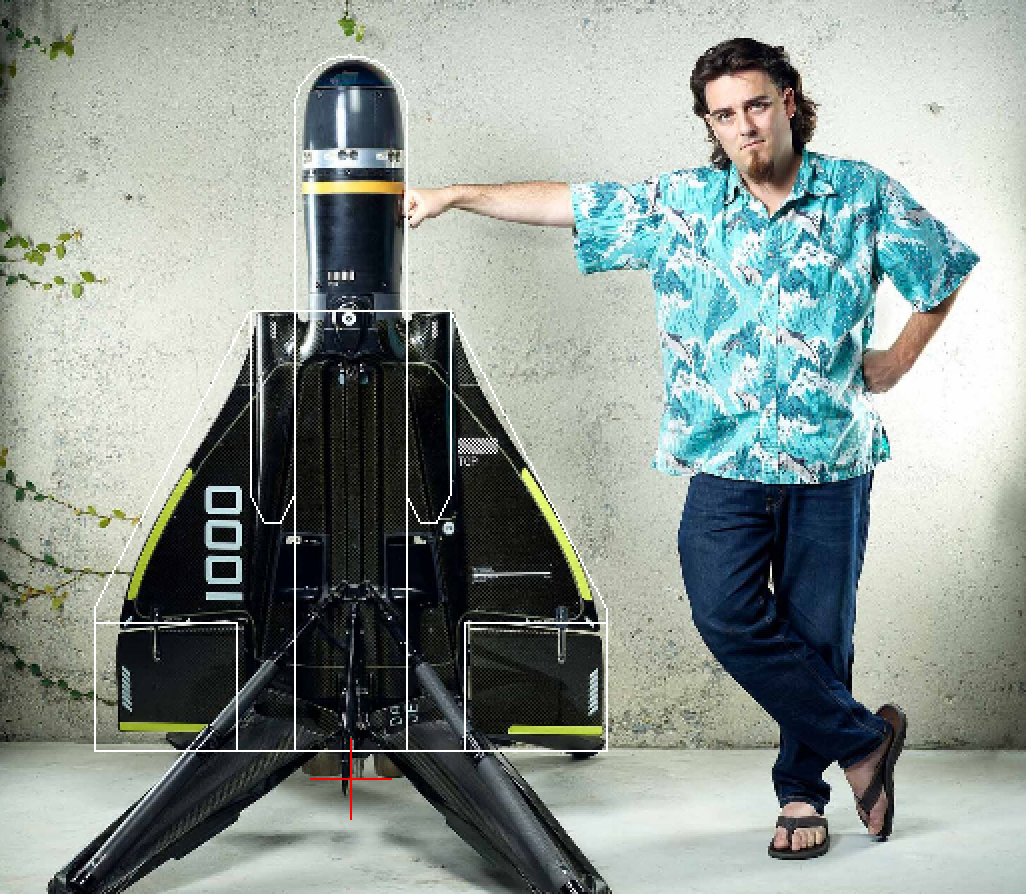

The purpose of this "toy" simulation is to estimate and evaluate the performance of a air vehicle I am calling "RR" based on what little information I am able to gather on the web about a similar real world product and time available. The overall planform dimensions were generated by importing a picture into 2D cad software (ref: [https://librecad.org/)](https://librecad.org/)) and scaling the image based on the estimated height of the person in the picture.

%clear; %clear the workspace

### English units

This simulation uses English units.

### Globals

G=32.174; %ft/s^2

### Simulation Limits

The simulation is limited to altitudes less than 30,000 ft and speeds less than mach 0.9.

### Vehicle

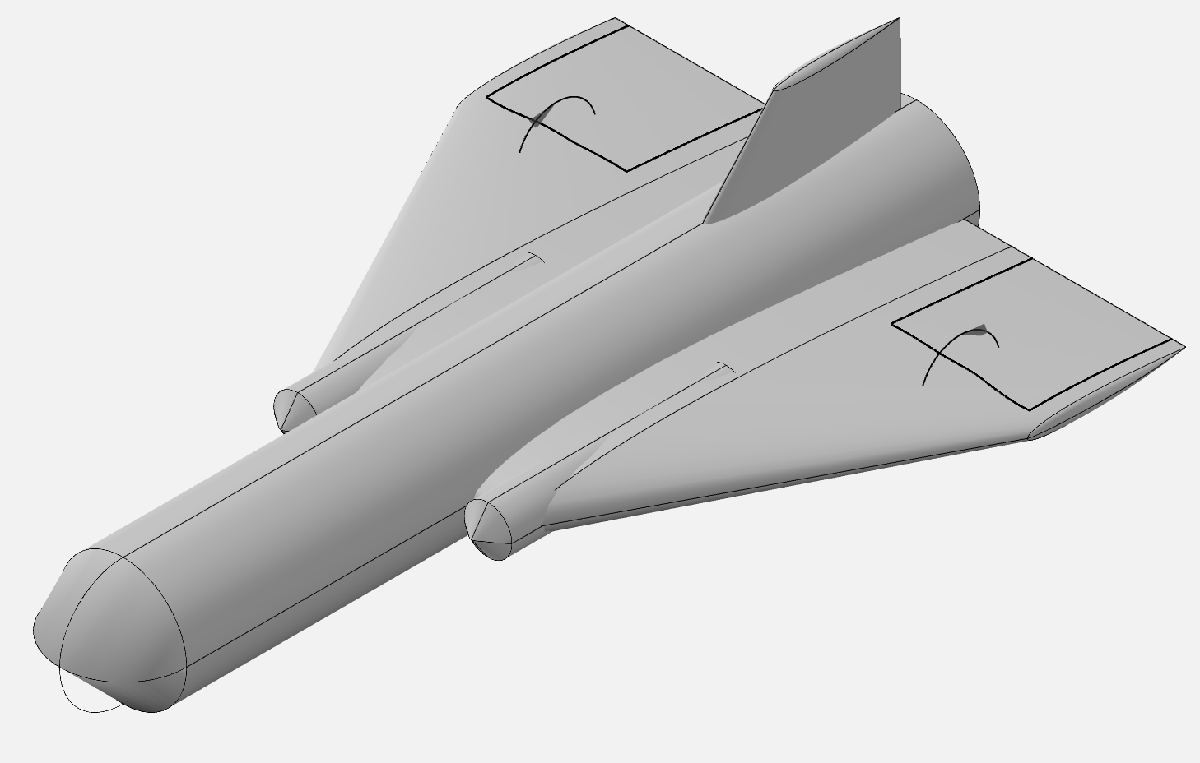

The planform measurements were transferred into OpenVSP and a 3D model was created as seen in the image above.

ref: [https://openvsp.org/](https://openvsp.org/)

RR_Len=5; %ft (from OpenVSP)
RR_Span=3.6; %ft (from OpenVSP)
RR_AERO_S=8.85; %ft^2 (from OpenVSP)              
RR_AERO_CORD=2.575; %ft (from OpenVSP)

For the vehicle airframe, I assume a light composite structure with very little metal, and estimate it at some factor heavier than high density foam.

ref: [https://www.owenscorning.com/en-us/insulation/products/foamular-250](https://www.owenscorning.com/en-us/insulation/products/foamular-250)

High_Density_Foam_Density=150/1000/1*12 ; %lbf/1000ft^2 1 in thick, 12in/ft -> lbf/ft^3
RR_Airframe_Mass_Density=1.5*High_Density_Foam_Density/G %slugs/ft^3

RR_Airframe_Mass_Density = 0.0839

### Propulsion

For propulsion I am using two Jet Cat turbojet engines and carrying two gallons of fuel.

ref: [https://www.jetcat.de/jetcat/anleitungen/DataSheet-P220-PRO-Versions-01-2023.pdf](https://www.jetcat.de/jetcat/anleitungen/DataSheet-P220-PRO-Versions-01-2023.pdf)

% Thrust range: 9-220N
RR_Motors_Thrust=convforce(2*[9,220],'N','lbf') %lbf

RR_Motors_Thrust =     4.0466   98.9159


RR_Fuel_Weight=2*6.8 %lbf 2 gallon kerosene

RR_Fuel_Weight = 13.6000

RR_Fuel_Mass=RR_Fuel_Weight/G %slugs 

RR_Fuel_Mass = 0.4227

% gal ft^3/7.48052gal
RR_Fuel_Volume=2.0/7.48052 %ft^3

RR_Fuel_Volume = 0.2674

% Fuel consumption: 130-725 ml/min l/1000ml min/60s ft^3/28.317l
RR_Fuel_Consumption=[130,725]/1000/60/28.317 %ft^3/s

RR_Fuel_Consumption = 1.0e-03 *

    0.0765    0.4267


% Fuel mass rate (dm/dt), ft^3/s 7.48052gal/ft^3 6.8lbf/gal 1/G
RR_Fuel_Mass_Rate=RR_Fuel_Consumption*7.48052*6.8/G % slugs/s

RR_Fuel_Mass_Rate = 1.0e-03 *

    0.1210    0.6746


RR_Fuel_Time=RR_Fuel_Volume/RR_Fuel_Consumption(2) % s

RR_Fuel_Time = 626.5543

RR_Mass_Fuel_Time=RR_Fuel_Mass/RR_Fuel_Mass_Rate(2) % s, validate

RR_Mass_Fuel_Time = 626.5543

The minimum mission time is ~10 minutes at full throttle before two gallons of fuel are exhausted.

% Weight: 1850g 
RR_Motors_Mass=convmass(2*1850/1000,'kg','slug') %slugs

RR_Motors_Mass = 0.2535

RR_Motors_Weight=RR_Motors_Mass*G %lbf 

RR_Motors_Weight = 8.1571

The motors thrust is estimated to decrease with altitude using a curve I found on the web. This would have to be followed up on with the vendor.

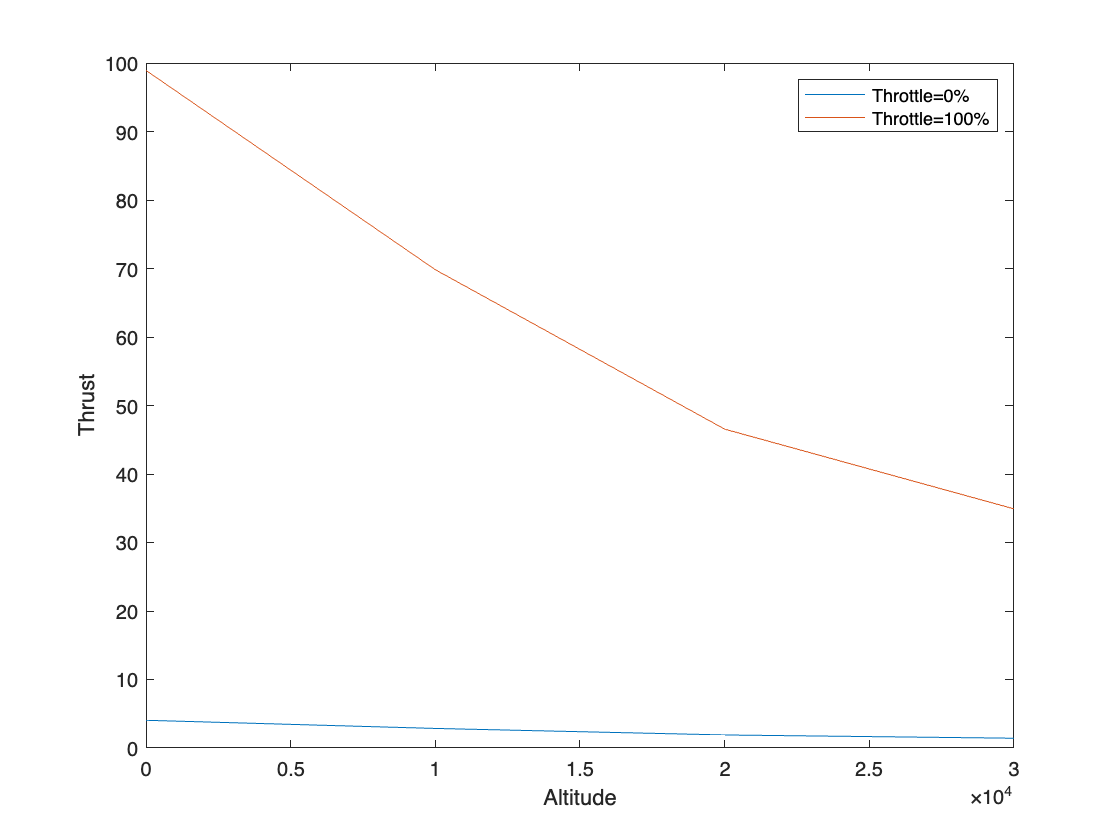

%Thrust vs Alt LUT (estimate)
RR_Motors_Thrust_Alt_Lut= [0.0 10000.0 20000.0 30000.0];
RR_Motors_Thrust_Pct_Lut= [17.0 12.0 8.0 6.0]/17.0;
%set(0,'DefaultAxesFontSize', 15);
plot(RR_Motors_Thrust_Alt_Lut,RR_Motors_Thrust_Pct_Lut*RR_Motors_Thrust(1), ...
    RR_Motors_Thrust_Alt_Lut,RR_Motors_Thrust_Pct_Lut*RR_Motors_Thrust(2));
xlabel('Altitude');
ylabel('Thrust');
legend('Throttle=0%','Throttle=100%')

### Aero Model

To determine the aerodynamic performance of the airframe, the OpenVSP 3D model was created as seen in the image above along with its coordinate axis. The origin of the simulation coordinate system is located at the center leading edge of the main wing.

### Aerodynamic Center

Using OpenVSP/VSPAERO a pitch stability simulation was run with the CG set to the origin to find the aerodynamic center.

RR_Aerodynamic_Center=0.9278426; %ft from leading edge of wing (from OpenVSP)

### Center of Gravity and Mass Rollup

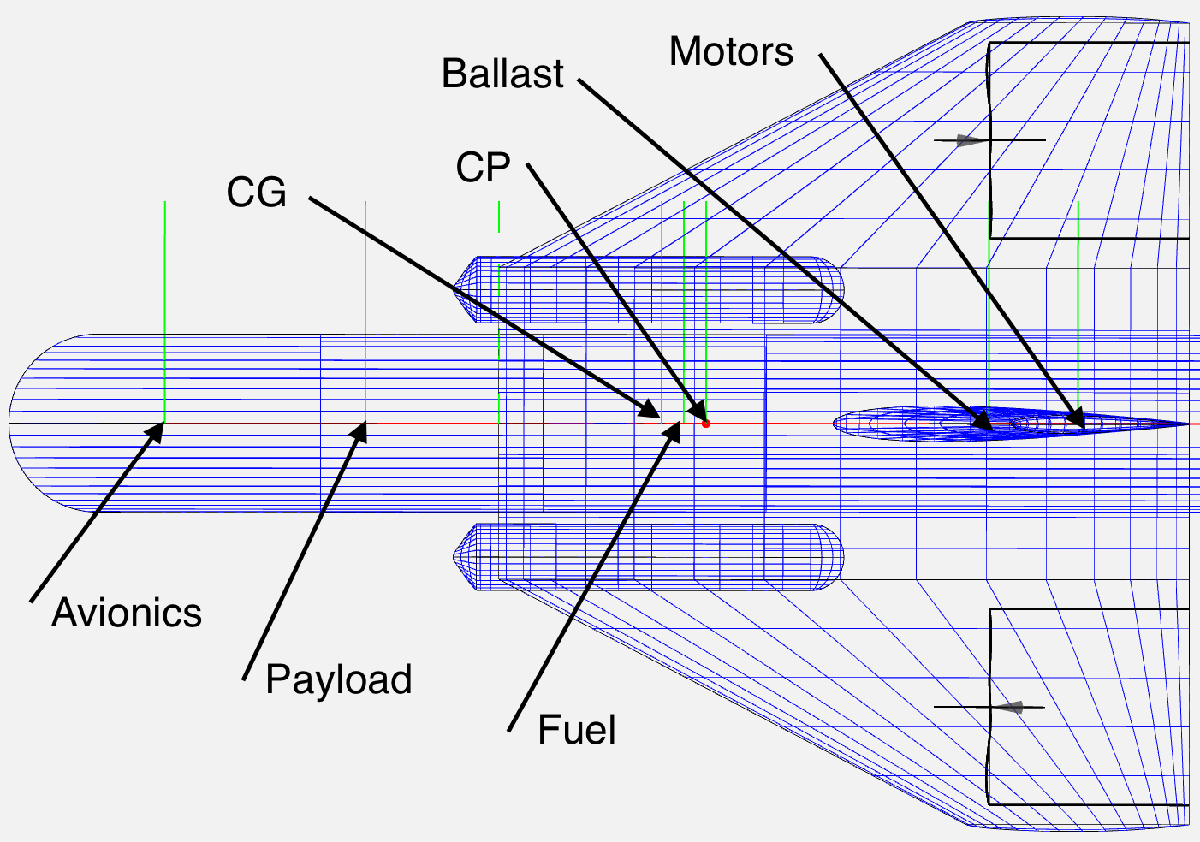

Knowing the aerodynamic center, OpenVSP mass properties analysis was run to calculate the overall mass of the vehicle and I set the center of gravity slightly ahead of aerodynamic center for stability.

%Remaining inputs for the mass model
RR_Avionics_Weight=10; %lbf (guess)
RR_Avionics_Mass=RR_Avionics_Weight/G %slugs 

RR_Avionics_Mass = 0.3108

RR_Payload_Weight=10; %lbf (guess)
RR_Payload_Mass=RR_Payload_Weight/G %slugs  

RR_Payload_Mass = 0.3108

RR_Ballast_Mass=0.35; %slugs to move CG
RR_Ballast_Weight=RR_Ballast_Mass*G %lbf

RR_Ballast_Weight = 11.2609

RR_Airframe_Mass=0.1319+0.1836+2*0.00312+2*0.00197 % slugs (from OpenVSP)

RR_Airframe_Mass = 0.3257

RR_Total_Mass=1.974; % slugs (from OpenVSP)
RR_CG=0.732; %ft from leading edge of wing (from OpenVSP)
RR_Iyy= 4.432; %slug-ft^2 (from OpenVSP)
RR_Total_Weight= RR_Total_Mass*G %lbf

RR_Total_Weight = 63.5115

RR_Total_Dry_Weight= RR_Total_Weight-RR_Fuel_Weight %lbf

RR_Total_Dry_Weight = 49.9115

RR_Total_Dry_Mass=RR_Total_Dry_Weight/G %slugs

RR_Total_Dry_Mass = 1.5513

RR_Thrust_To_Weight=RR_Motors_Thrust(2)/RR_Total_Dry_Weight 

RR_Thrust_To_Weight = 1.9818

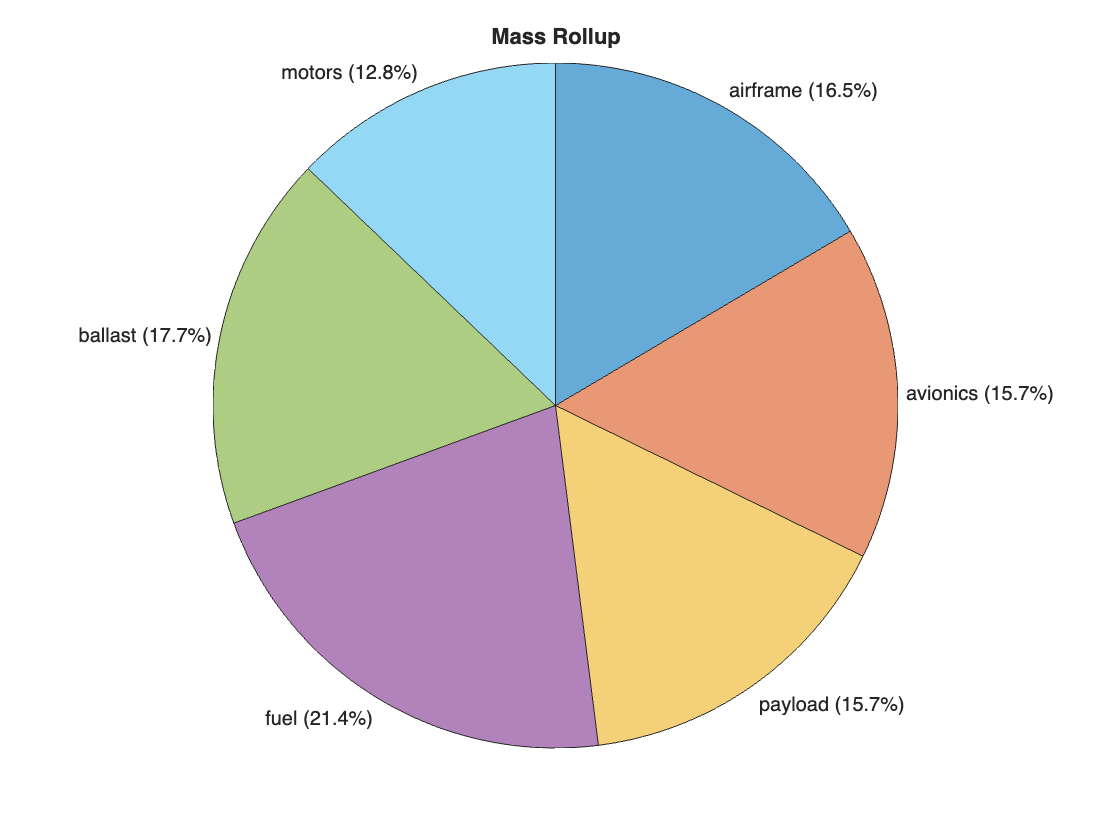

h=piechart([RR_Airframe_Mass RR_Avionics_Mass RR_Payload_Mass ...
    RR_Fuel_Mass RR_Ballast_Mass RR_Motors_Mass], ...
    ["airframe" "avionics" "payload" "fuel" "ballast" "motors"]);
h.Title='Mass Rollup';

### Stability 

After setting the center of gravity, OpenVSP/VSPAERO was run with stability on to find the stability margin.

RR_X_CG=0.7324250; % ft from leading edge of wing (from OpenVSP)
RR_SM=0.0716877; % 7% stablity margin (OpenVSP, 5-40% typical range)             
RR_X_NP=0.9170209; % ft from leading edge of wing (from OpenVSP)
RR_CMYQ=-1.210696; % pitch moment dampening (from OpenVSP)

With the current center of gravity, the result is seven percent positive stability margin which is adequate but will still allow for aggressive maneuvering.

### Parasitic Drag

Zero angle of attack drag was simulated using the parasitic drag tool in OpenVSP and look up tables were generated.

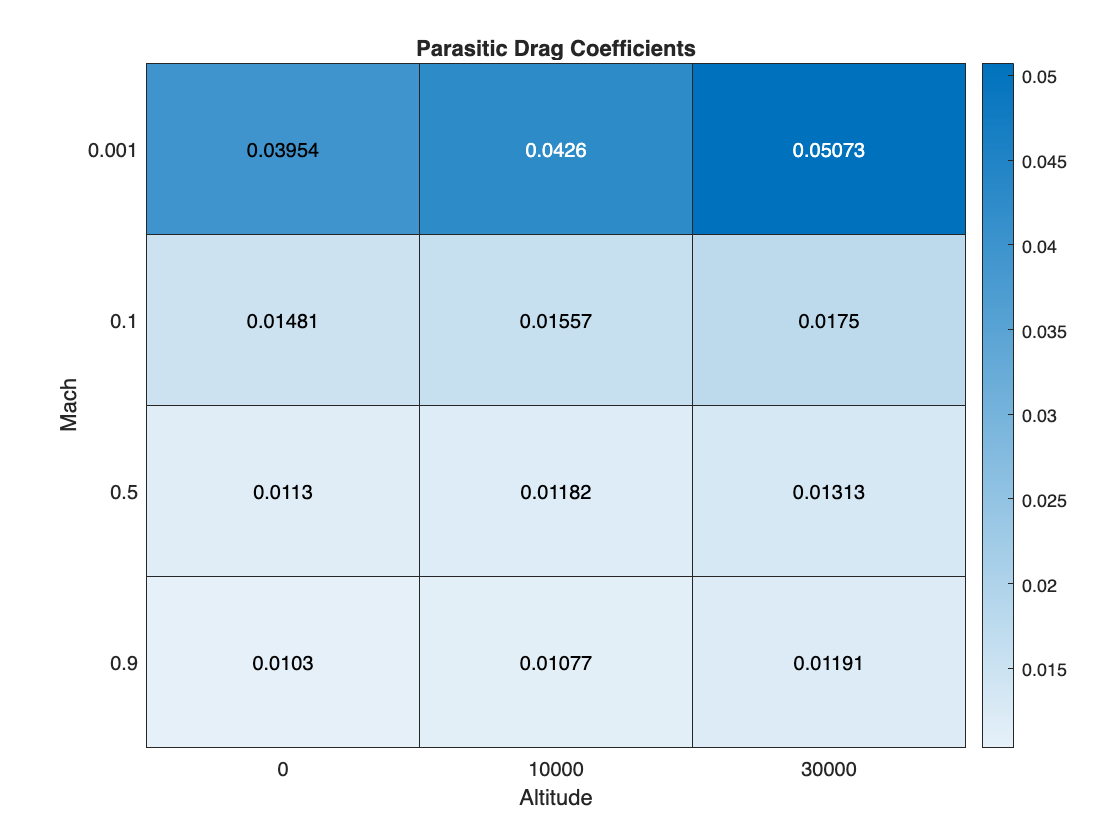

% 2D Parasitic Drag lookup table (from OpenVSP)
RR_PD_ALT=[0.0 10000.0 30000.0];
RR_PD_MACH=[0.001 0.1 0.5 0.9];
RR_PD_CD=[ 0.03954 0.04260 0.05073;
    0.01481 0.01557 0.01750;
    0.01130 0.01182 0.01313;
    0.01030 0.01077 0.01191; ];

h=heatmap(RR_PD_ALT,RR_PD_MACH,RR_PD_CD);
h.Title = 'Parasitic Drag Coefficients';
h.XLabel = 'Altitude';
h.YLabel = 'Mach';

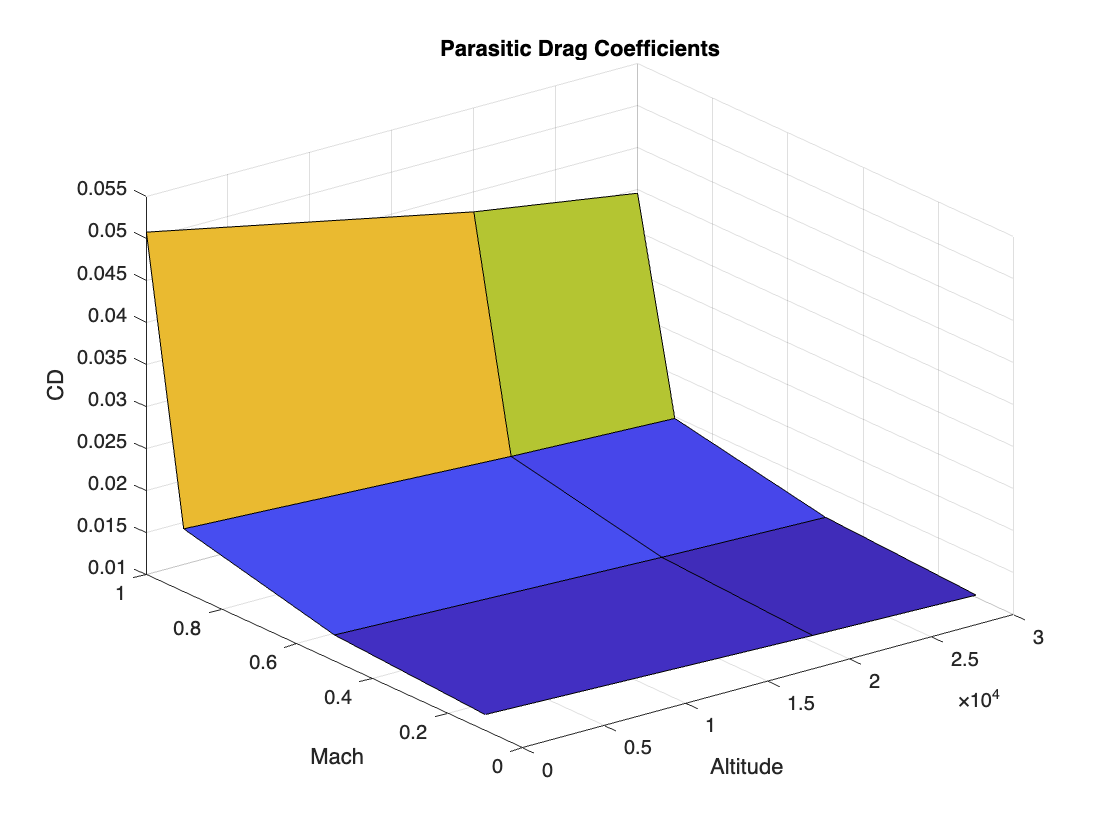

h=surf(RR_PD_ALT,RR_PD_MACH,RR_PD_CD);
title('Parasitic Drag Coefficients');
xlabel('Altitude');
ylabel('Mach');
zlabel('CD');
rotate(h,[0 0 1],180);

### Aerodynamic Forces

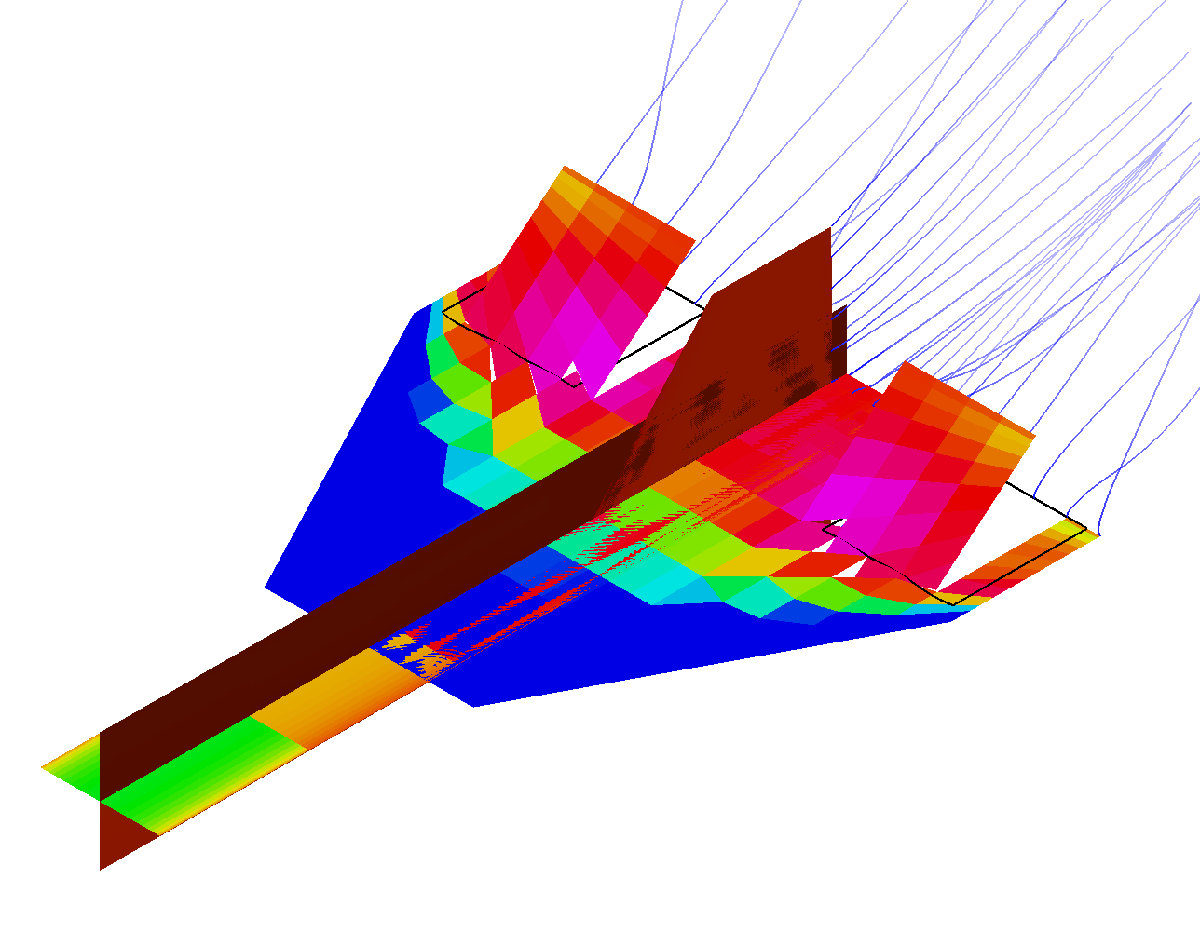

To collect data for the X,Y,Pitch simulation in Simulink, the angle of attack and elevon angle was varied in OpenVSP/VSPAERO and look up tables were generated. The fin and wing use symmetrical airfoils which is why there is symmetry in the results.

run("aero.m");

RR_Aero_Aoa 

RR_Aero_Aoa =    -40   -20   -10    -5     0     5    10    20    40


RR_Aero_Elevons

RR_Aero_Elevons =    -40   -20   -10    -5     0     5    10    20    40


RR_Aero_Mach

RR_Aero_Mach =     0.0100    0.1000    0.2000    0.5000    0.9000


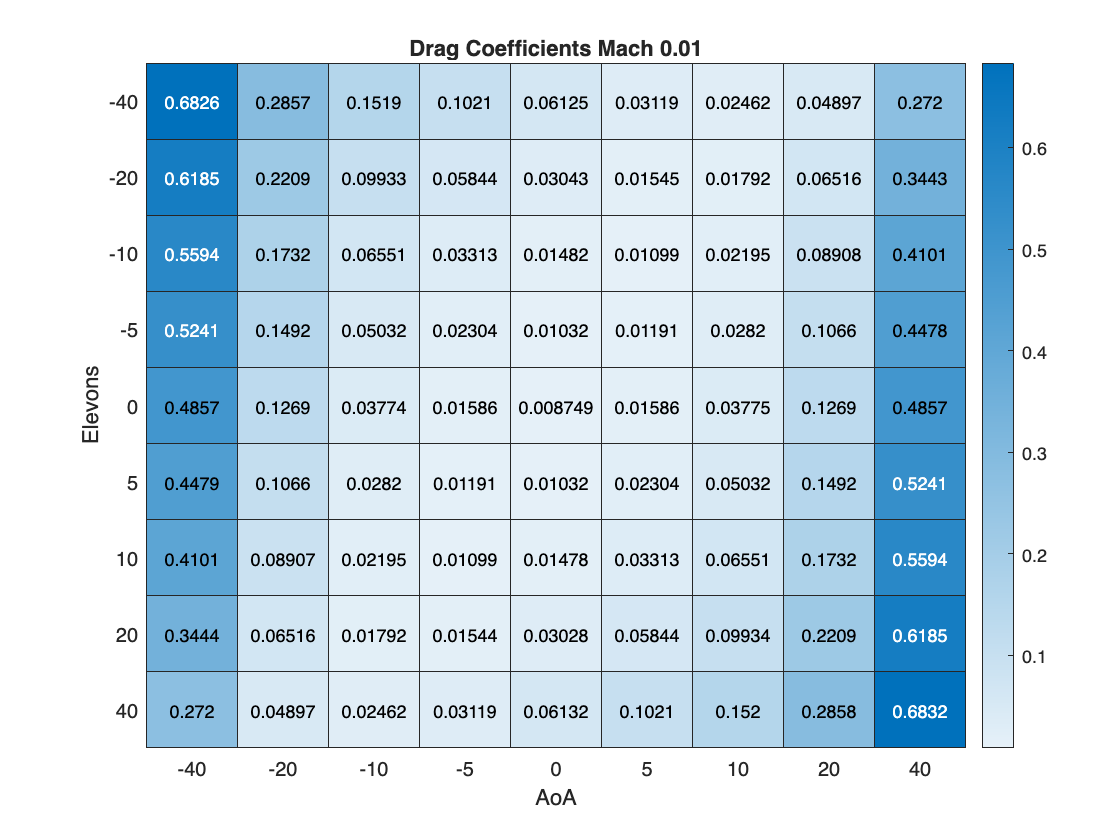

h=heatmap(RR_Aero_Aoa, RR_Aero_Elevons, RR_Aero_CD(:,:,1));
h.Title='Drag Coefficients Mach 0.01';
h.XLabel='AoA';
h.YLabel='Elevons';

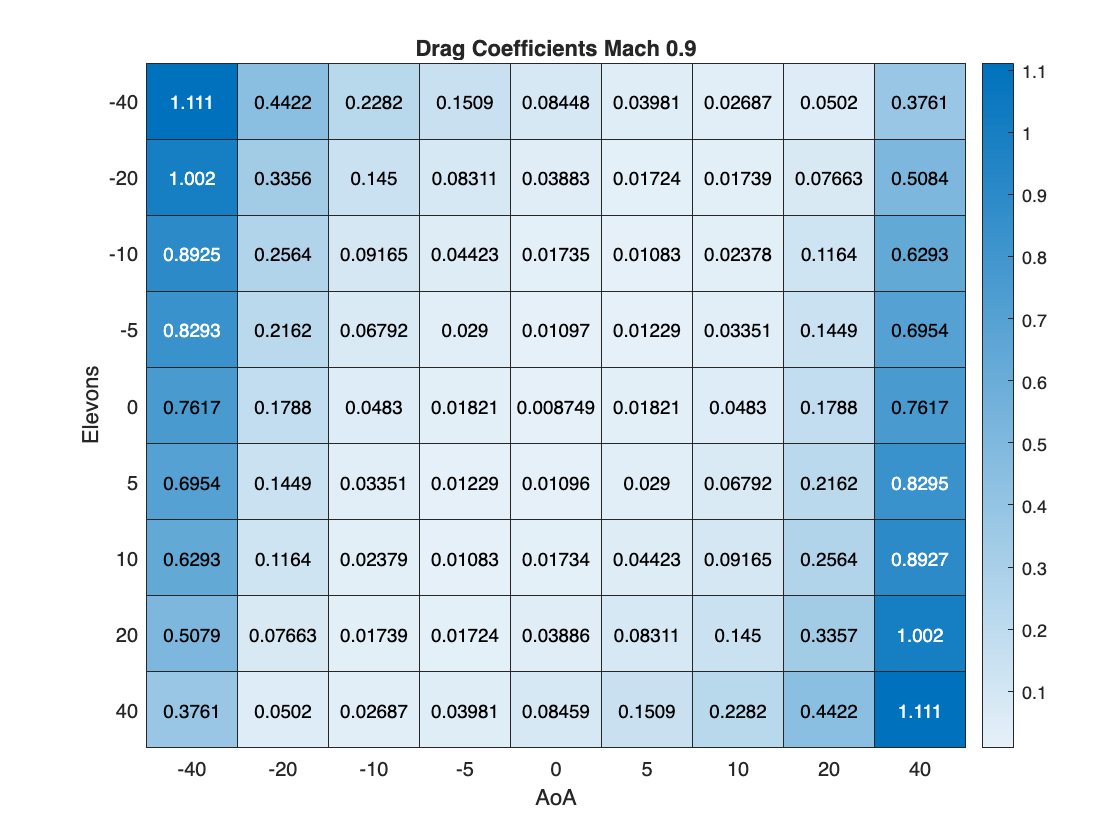

h=heatmap(RR_Aero_Aoa, RR_Aero_Elevons, RR_Aero_CD(:,:,5));
h.Title='Drag Coefficients Mach 0.9';
h.XLabel='AoA';
h.YLabel='Elevons';

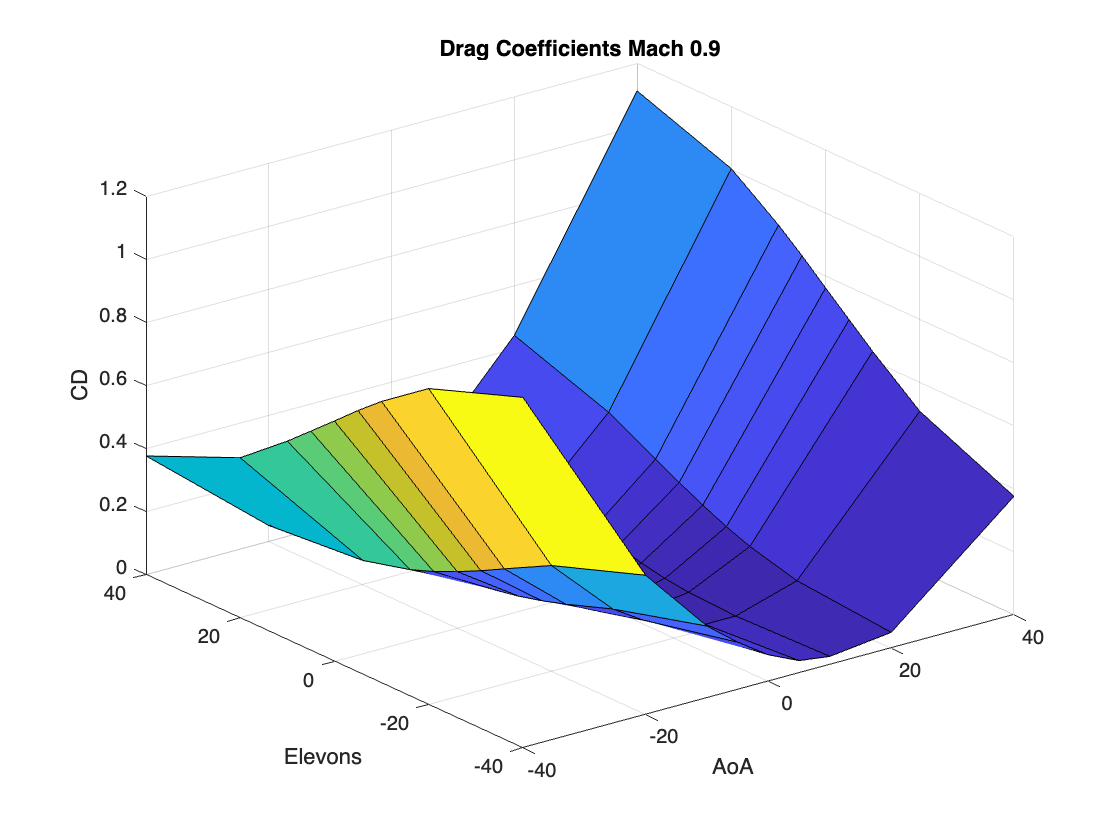

surf(RR_Aero_Aoa, RR_Aero_Elevons, RR_Aero_CD(:,:,5));
title('Drag Coefficients Mach 0.9');
xlabel('AoA');
ylabel('Elevons');
zlabel('CD');

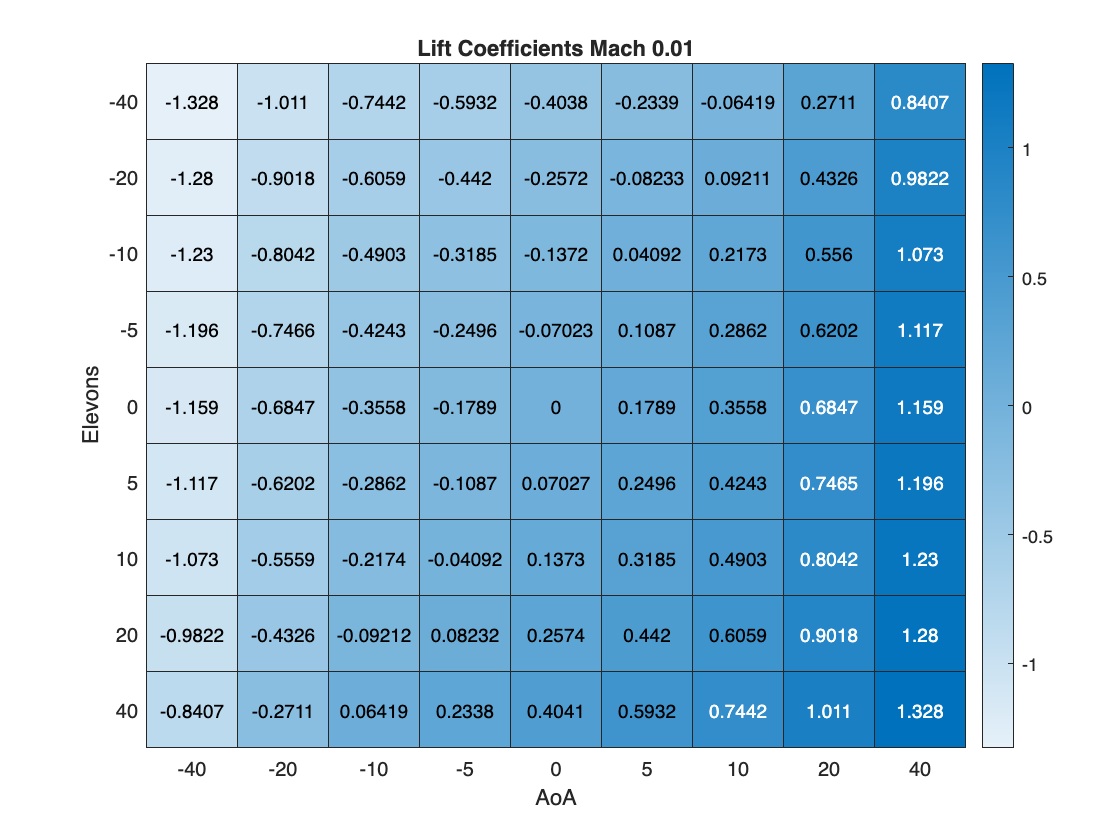

h=heatmap(RR_Aero_Aoa, RR_Aero_Elevons, RR_Aero_CL(:,:,1));
h.Title='Lift Coefficients Mach 0.01';
h.XLabel='AoA';
h.YLabel='Elevons';

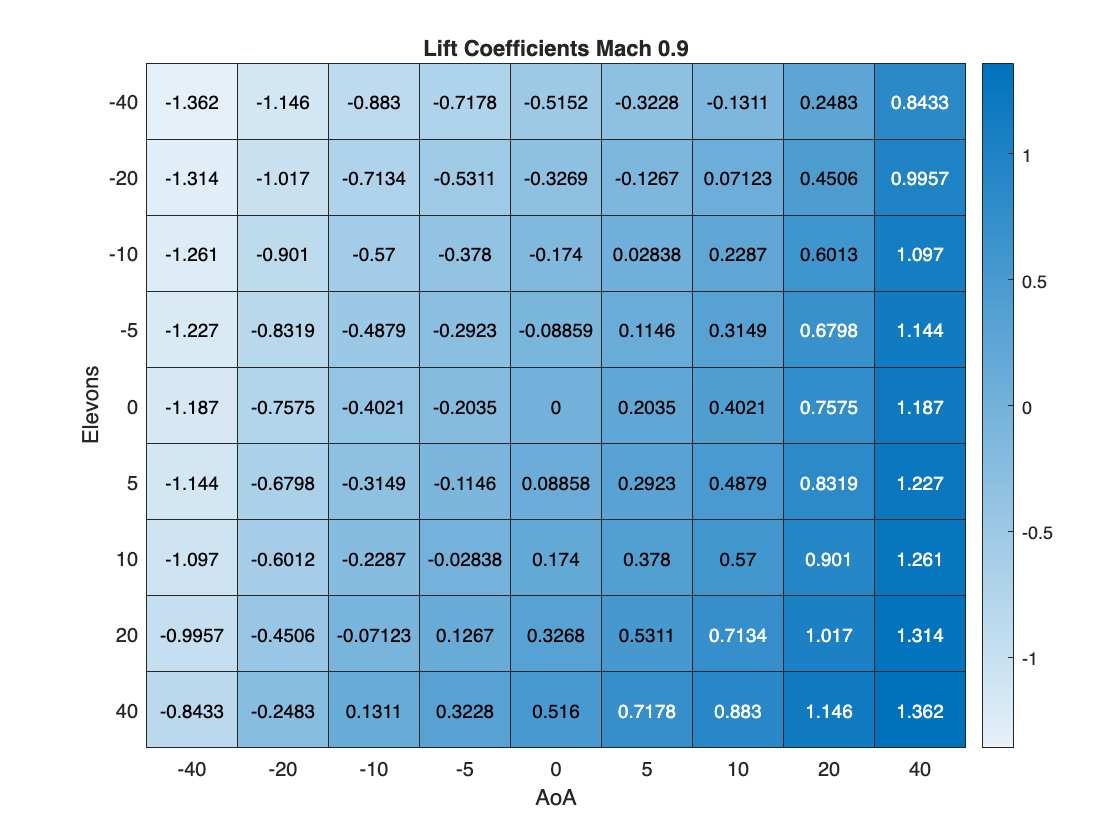

h=heatmap(RR_Aero_Aoa, RR_Aero_Elevons, RR_Aero_CL(:,:,5));
h.Title='Lift Coefficients Mach 0.9';
h.XLabel='AoA';
h.YLabel='Elevons';

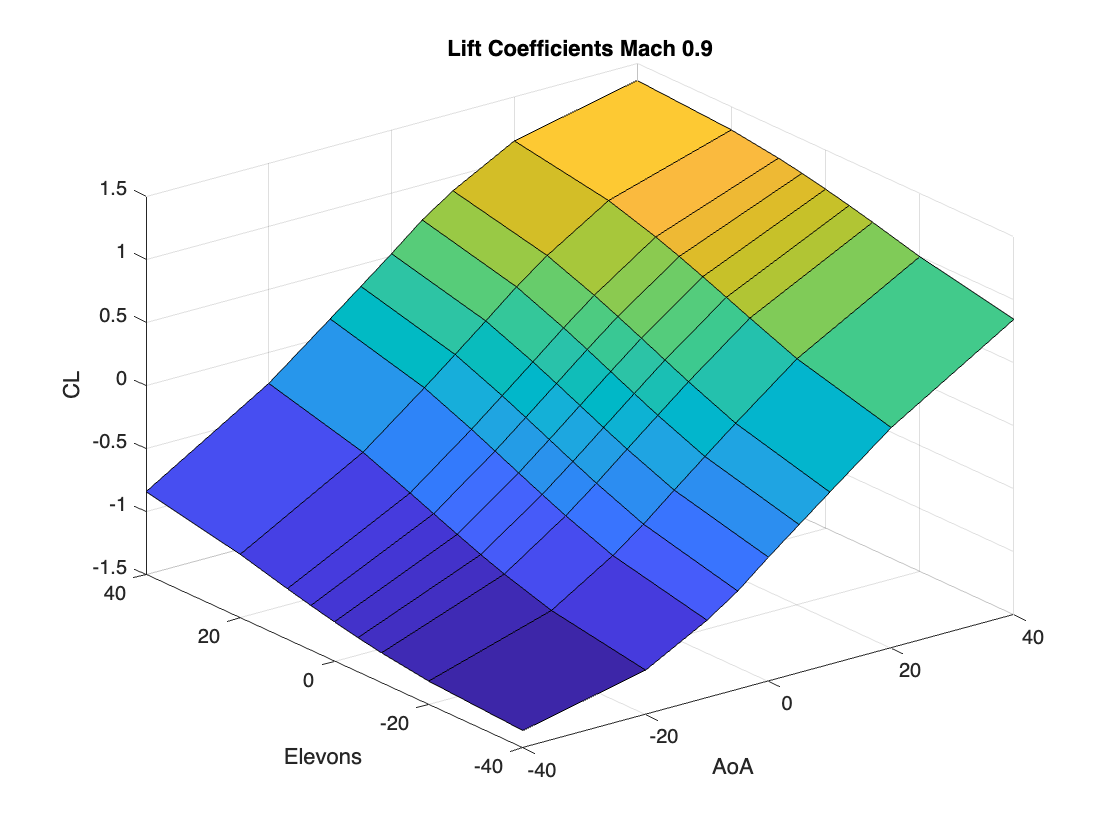

surf(RR_Aero_Aoa, RR_Aero_Elevons, RR_Aero_CL(:,:,5));
title('Lift Coefficients Mach 0.9');
xlabel('AoA');
ylabel('Elevons');
zlabel('CL');

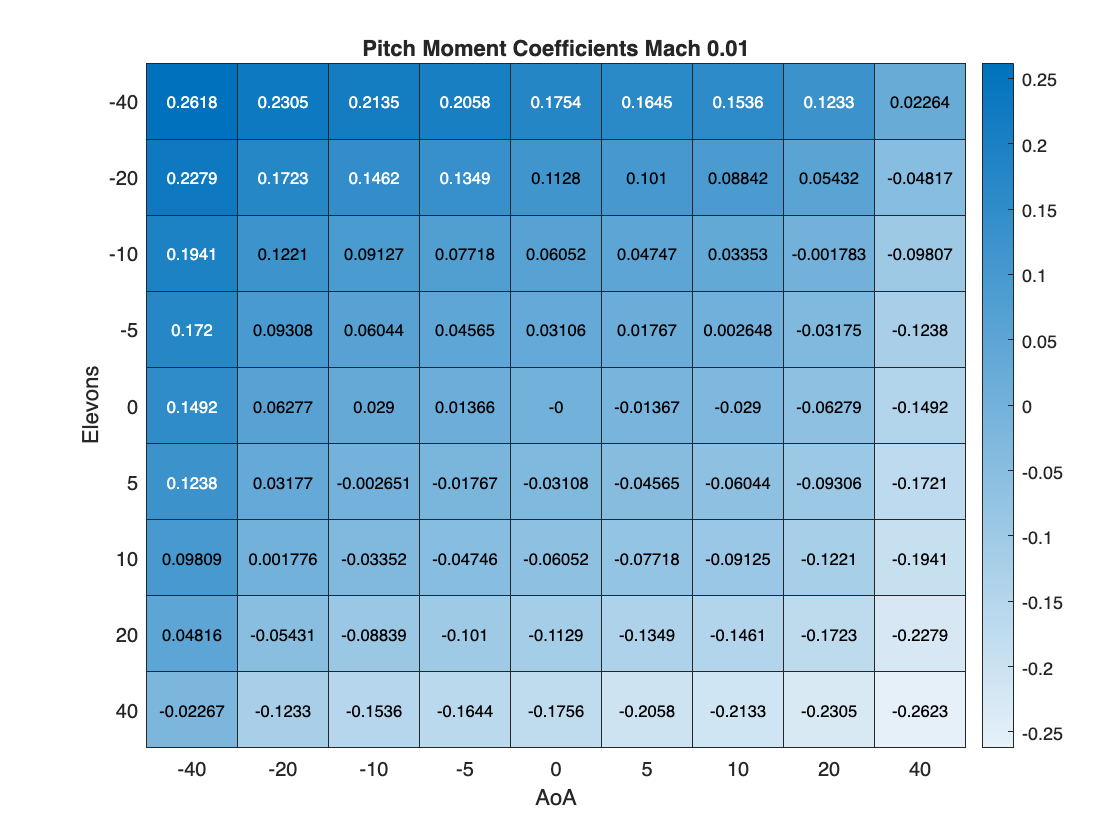

h=heatmap(RR_Aero_Aoa, RR_Aero_Elevons, RR_Aero_CMy(:,:,1));
h.Title='Pitch Moment Coefficients Mach 0.01';
h.XLabel='AoA';
h.YLabel='Elevons';

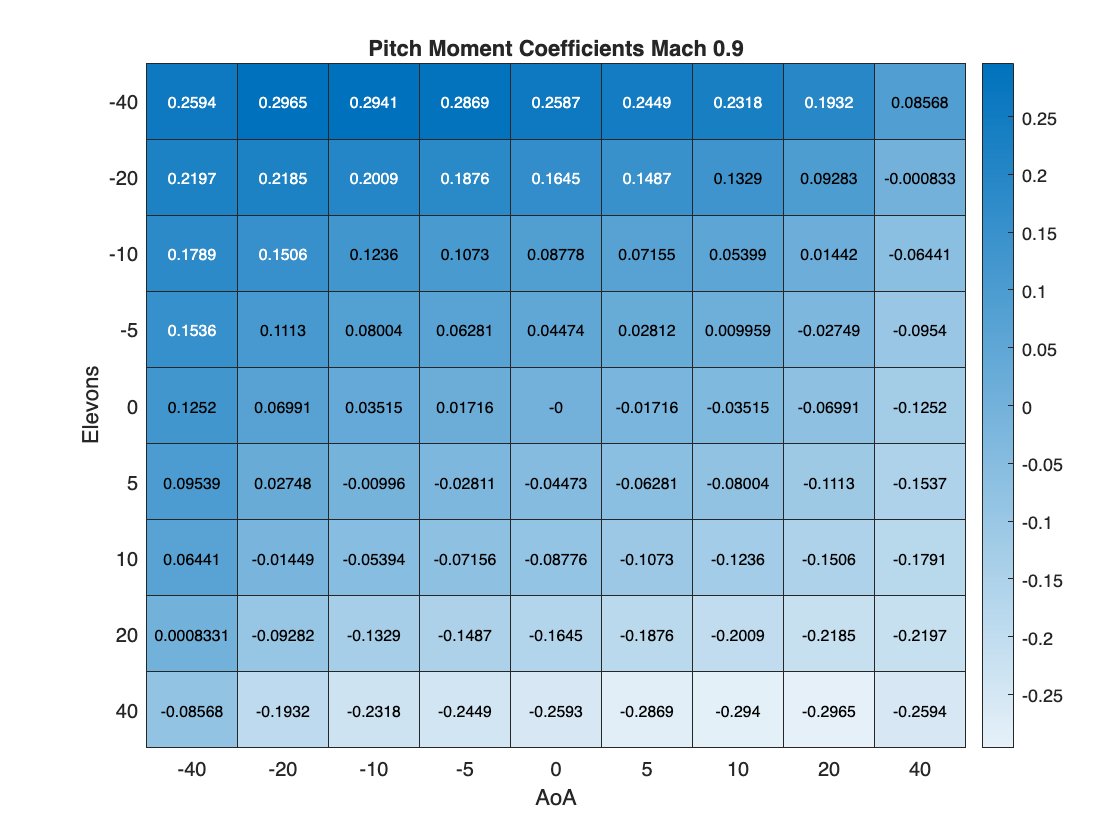

h=heatmap(RR_Aero_Aoa, RR_Aero_Elevons, RR_Aero_CMy(:,:,5));
h.Title='Pitch Moment Coefficients Mach 0.9';
h.XLabel='AoA';
h.YLabel='Elevons';

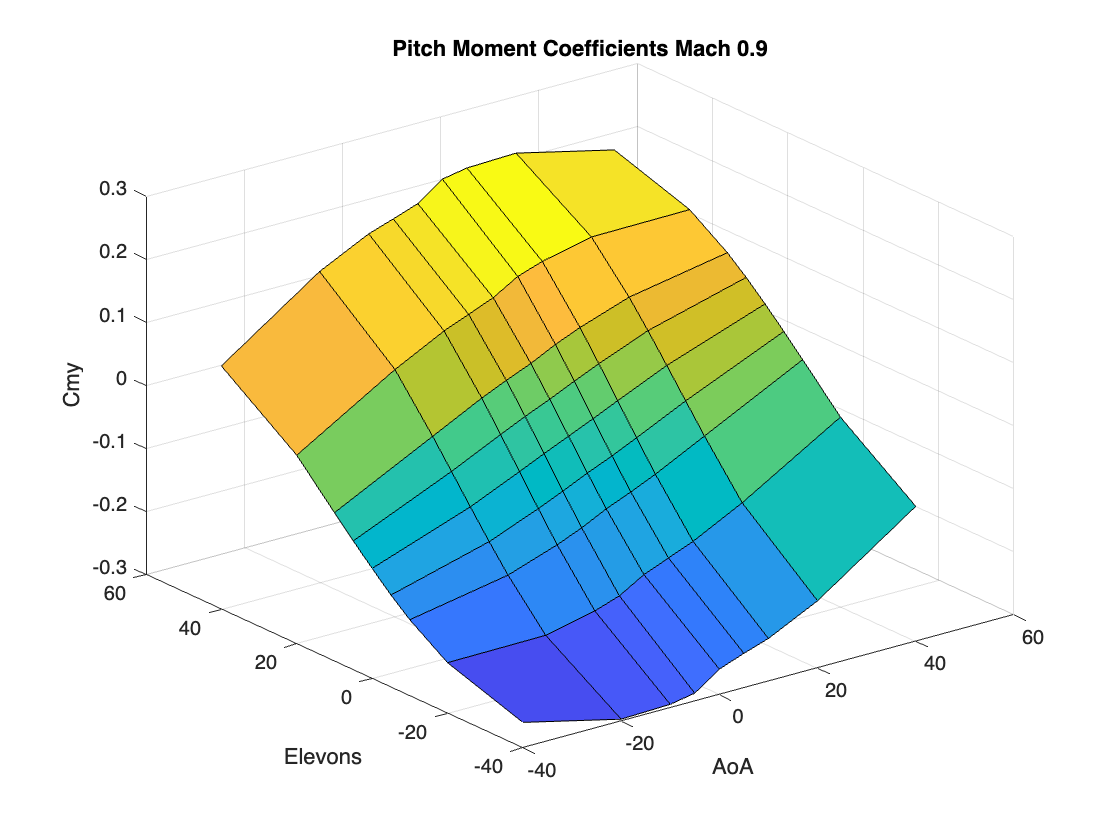

h=surf(RR_Aero_Aoa, RR_Aero_Elevons, RR_Aero_CMy(:,:,5));
title('Pitch Moment Coefficients Mach 0.9');
xlabel('AoA');
ylabel('Elevons');
zlabel('Cmy');
rotate(h,[0 0 1],180);

### Save Workspace

With all this data about the RR vehicle I'm ready to save the data from the workspace for Simulink simulations.

save('RR.mat');